if ~exist('mount_database.mat', 'file')
    generateMountDatabase();
end
load('mount_database.mat');

image_folder = 'Test_Images';
image_filename = 'test5.jpg';  
image_path = fullfile(image_folder, image_filename);
original_image = imread(image_path);

%desired_base_size = [2000, 2000]; 
%base_image = imresize(original_image, desired_base_size)
desired_base_size = 3000; % Adjust this to your desired size
base_image = resizeImage(original_image, [desired_base_size, NaN]);

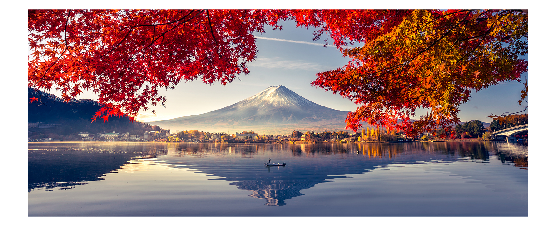


tile_size = 25; 
mount_size = [25, 25]; 

reconstructed_image = reconstructImage(base_image, mount_data, tile_size, mount_size, 'lab');
imshow(original_image)

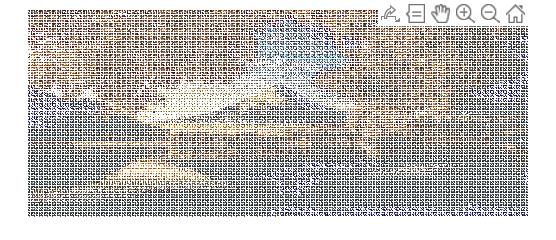

imshow(reconstructed_image);